### Bubble nucleation and growth in rhyolite

This code shows a sample run for bubble nucleation and growth model

By Sahand Hajimirza. 

For detailed description of the model, see Hajimirza et. al. 2019. 

Experimental conditions

% Experimental conditions

Pi = 200;                   % Initial pressure [MPa]
Pf = 20;                    % Final pressure

td = 5;                     % Decompressio time [s]
tpost = 5;                  % Post decompression time [s]

dPdt = (Pi-Pf)./td;         % Decompression rate

T = 850 * ones(size(Pi));   % Temperature  

% Generating the experimental conditions table.
In = table(Pi,Pf,dPdt,td,tpost,T)

In = 1×6 table
    Pi     Pf    dPdt    td    tpost     T 
    ___    __    ____    __    _____    ___

    200    20     36     5       5      850


Running the model

[BND,tData] = Bubble_Nucleation_Growth(In);

% Final Bubble number density
disp(BND)

   1.6173e+15



Plotting the evolution of model parameters through time

figure

set(0, 'DefaultAxesFontName', 'Arial');
set(0, 'DefaultTextFontName', 'Arial');
set(0, 'DefaultAxesFontSize', 8);
set(0, 'DefaultTextFontSize', 8);
set(0,'DefaultPatchEdgeColor','none');
set(0,'DefaultAxesBox','on');
set(0, 'DefaultTextInterpreter', 'latex');

ssize = 5;       % Marker Size
linewidth = 1;

i = 1

i = 1

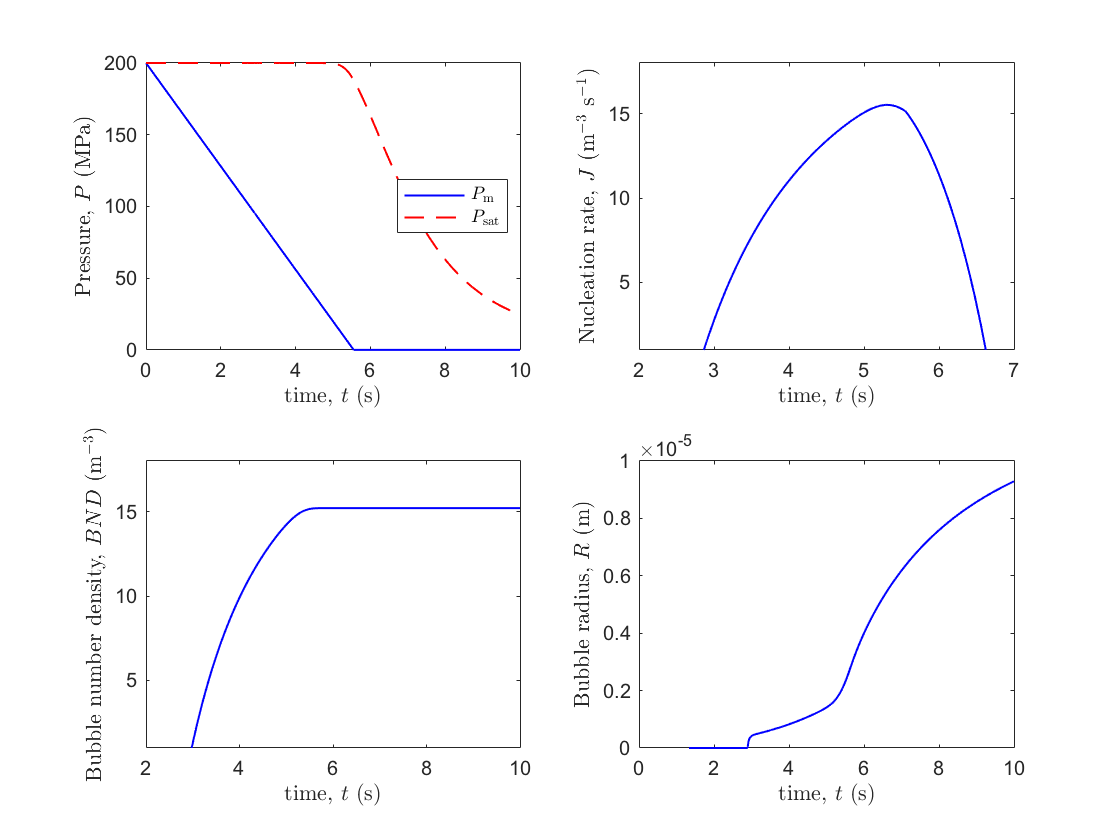

subplot(2,2,i)
hold on
plot(tData.t,tData.pm/1e6,'b','LineWidth',linewidth)
plot(tData.t,tData.psat/1e6,'r--','LineWidth',linewidth)
l1 = legend('$P_{\rm m}$','$P_{\rm sat}$','Location','east');
l1.Interpreter = 'latex';
ax(i) = gca;
ax(i).XLabel.String = ('time, $t$ (s)');
ax(i).YLabel.String = ('Pressure, $P$ (MPa)');


i = i + 1;
subplot(2,2,i)
plot(tData.t,log10(tData.J),'b','LineWidth',linewidth); 
ax(i) = gca;
ax(i).XLabel.String = ('time, $t$ (s)');
ax(i).YLabel.String = ('Nucleation rate, $J$ (m$^{-3}$ s$^{-1}$)');
ylim([1 18])

i = i + 1;
subplot(2,2,i)
plot(tData.t,log10(tData.M0),'b','LineWidth',linewidth); 
ax(i) = gca;
ax(i).XLabel.String = ('time, $t$ (s)');
ax(i).YLabel.String = ('Bubble number density, $BND$ (m$^{-3}$)');
ylim([1 18])


i = i + 1;
subplot(2,2,i)
plot(tData.t,tData.M1./tData.M0,'b','LineWidth',linewidth); 
ax(i) = gca;
ax(i).XLabel.String = ('time, $t$ (s)');
ax(i).YLabel.String = ('Bubble radius, $R$ (m)');

The code supports parallel run. To run parallel, the experimental condition table must be consisted of multiple rows, where each row represent a experimental condition. 

In = table(Pi,Pf,dPdt,td,tpost,T);
In = repmat(In,3);
In.td(2) = 20;
In.td(3) = 40;
In

In = 3×18 table
    Pi     Pf    dPdt    td    tpost     T     Pi_1    Pf_1    dPdt_1    td_1    tpost_1    T_1    Pi_2    Pf_2    dPdt_2    td_2    tpost_2    T_2
    ___    __    ____    __    _____    ___    ____    ____    ______    ____    _______    ___    ____    ____    ______    ____    _______    ___

    200    20     36      5      5      850    200      20       36       5


parfor i = 1:length(In.Pi)
    [BND(i,1),tData(i)] = Bubble_Nucleation_Growth(In);
end

